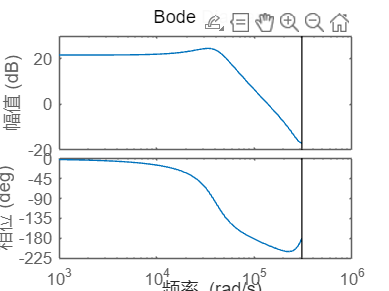

clear all;

D_val = 0.274997402487289;
Ts_val = 1/(97516.8093926517);
Ts=Ts_val;
D=D_val;
V_IN=12;
L_f = 6e-6;
R_Ld = 0.33;
C_f = 100e-6;
R_c = 10e-3;
H_v=1;
DCR=0;
%Se, 0;
Se=(200e-6)/(10e-9);
Td= 0.5*Ts;


A_on = [-(R_Ld*R_c + DCR*R_Ld + DCR*R_c)/(L_f*(R_Ld + R_c)), -R_Ld/(L_f*(R_Ld + R_c)); R_Ld/(C_f*(R_Ld + R_c)), -1/(C_f*(R_Ld + R_c))];
A_off = A_on;
B_on = [1/L_f; sym(0)];
B_off = [sym(0); sym(0)];
C_on = [(R_Ld*R_c)/(R_Ld + R_c), R_Ld/(R_Ld + R_c)];
C_off = C_on;
D_on = 0;
D_off = 0;
A1 = A_on;
A2 = A_on;
B1= B_on;
B2=B_off;



n  = size(A1,1);


%% ---------- (2) 计算 alpha ----------
alpha = (B1 - B2)*V_IN;   % 你的式(5)

%% ---------- (3) 计算 Phi, Gamma （trailing-edge, interval-2） ----------
Phi   = expm(A2*(Ts - Td)) * expm(A1*(D*Ts)) * expm(A2*(Td - D*Ts));
Gamma = expm(A2*(Ts - Td)) * (alpha * Ts);   % 输入为  \hat t
Phi = double(Phi);
Gamma = double(Gamma);
%% ---------- (4) 输出矩阵（按你的说明：C_off） ----------
C_d = C_off;  % C_off
D_d = 0;

%% ---------- (5) 构造离散状态空间（输入为：开关时刻扰动 \hat t） ----------
sysd = ss(Phi, Gamma, C_d, D_d, Ts);
bode(sysd)

%% ---------- (6) 基本检查 ----------
disp('eig(Phi) = '); disp(eig(Phi).');

eig(Phi) = 
   0.7919 + 0.3168i   0.7919 - 0.3168i



z = 1;  % 简单查看 z=1 处的静态增益（若 z=1 是极点需用极限）
Gz = C_d*((z*eye(n) - Phi)\Gamma) + D_d;
disp('gain at z=1 from \hat t to y:'); disp(Gz);

gain at z=1 from \hat t to y:
   12.0826

